# Problem 4: Attitude dynamics

Student 1: Álvaro Reviriego Moreno

Student 2: Enrique Sentana Gómez

Data of the problem:

clear all;
close all;
muE = 398600; % mu Earth, km^3/s^2 
RE = 6371; % km
zetap = 600; % km
e = 0.1; % -
a =  RE + zetap; % km 
w = [0,0,1]; % Equatorial orbit

## Nominal $\mathbf\omega_{b0}$

In this section the goal is to obtain a function that computes the nominal angular velocity vector $$\vec{\omega_{b0}}$$ (in basis B0) to keep the Nadir orientation in the orbit defined by $\mu$, a, e, and $\vec{w}$ (unit vector along h), as a function of the true anomally which is going to be defined in this work as $\nu
$.

For this purpose a function named nominal_hw is going to developed in such a way that introducing as inputs $\mu$, a, e, $\vec{w}$ and $\nu
$, it retunrns the value of $$\vec{\omega_{b0}}$$ in basis B0. First the function computes the orbit parameter also named as semi-latus rectum.


$$p = a(1-e^{2})$$


Next, the angular momentum is obtained by getting its magnitude first and then projecting it onto $\vec{w}$.


$$h = \sqrt{p\mu}\\

\vec{h}=h\vec{w}$$


Following, the angular rate at that instant needs to be obtained.


$$r = p/(1+ecos(\nu))
 $$



$$\dot{\theta} = h/r^2$$


Finally, the nominal angular velocity vector can be computed.


$$\vec{\omega_{b0}} = \dot{\theta} \vec{w}$$


To complete this task, the three components of the nominal angular velocity vector for a full orbit as a function of time is plotted. To do this, $\vec{\omega_{b0}$ is obtained for $\nu = [0\ 360]^\circ$.

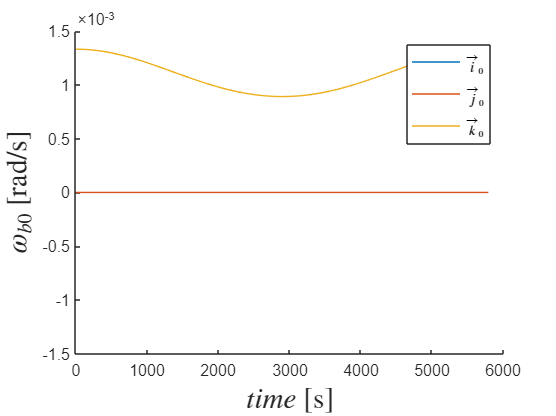

N = 360;
nu = linspace(0,2*pi,N); 
omega_b0 = zeros(3,N);
n = sqrt(muE/a^3);

for i = 1:N
   omega_b0(:,i) = nominal_hw(muE,a,e,w,nu(i));
   t(i) = nu(i)/n;
end 

figure(1)
hold on 
plot(t,omega_b0(1,:))
plot(t,omega_b0(2,:))
plot(t,omega_b0(3,:))
ylim([-1.5e-3,1.5e-3])
xlabel('$time$ [s]','Interpreter','latex','FontSize',18)
ylabel('$\omega_{b0}$ [rad/s]','Interpreter','latex','FontSize',18)
legend('$\vec i_{0}$','$\vec j_{0}$','$\vec k_{0}$','Interpreter','latex')

## Euler angle derivatives

For this section, the purpose is to develop a function that returns the time derivative of the three Euler angles of Sb with respect to Sℓ. The inputs required for this function are the orbit data, the true anomaly $\nu
$, the current angles and $$\vec{\omega_{b0}}$$ in S0. It is also set that the Euler angles and their derivatives habe to be a row vector.


$$\omega_{x} = \dot{\theta}cos(\psi)+\dot{\phi}sin(\theta)sin(\psi)\\

\omega_{y} = \dot{\theta}sin(\psi) - \dot{\phi}sin(\theta)cos(\psi)\\

\omega_{z} = \dot{\phi}cos(\theta) + \dot{\psi}$$


Finally, the derivatives of the three Euler angles are obtained from the previous set of equations. Their expressions are as it follows.


$$\dot{\phi} = \frac{1}{sin(\theta)}(\frac{2 \omega_{x}}{sin(\psi)}- \omega_{y}cos(\psi) - \omega_{x}sin(\psi)$$



$$\dot{\theta} = \omega_{y} sin(\psi) + \omega_{x} cos(\psi) $$



$$\dot{\psi} = \omega_{z} - \dot{\phi} cos(\theta)$$


To complete this part of the report, it is asked to show that by inputing the nominal $$\vec{\omega_{b0}}$$ obtained in the first section, the Euler angle derivatives are indeed 0 for the entire orbit.

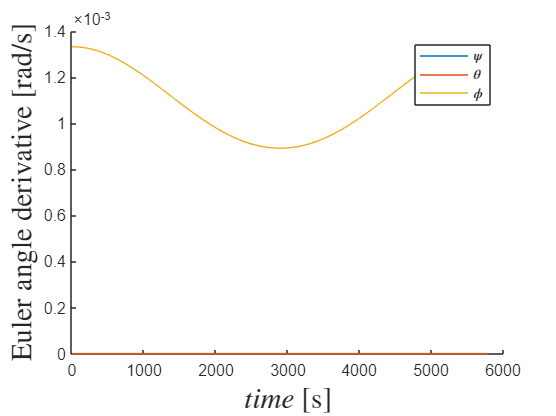

% nominal Euler angles
angles= [0 pi/2 0];
%dangles_dt = zeros(3,N);

for i=1:N
    danglesdt(:,i) = dangles_dt(muE,a,e,w,nu(i),angles,omega_b0(:,i));
end

figure
hold on
plot(t,danglesdt(1,:))
plot(t,danglesdt(2,:))
plot(t,danglesdt(3,:))
xlabel('$time$ [s]','Interpreter','latex','FontSize',18)
ylabel('Euler angle derivative [rad/s]','Interpreter','latex','FontSize',18)
legend('$\psi$','$\theta$','$\phi$','Interpreter','latex')
hold off

## Wheel rates

In this task, a function that obtains the required sacalar angular rates of the three wheels to maintain the desired angular velocity $$\vec{\omega_{b0}}$$ (in basis B0). The inputs for this purpose are the $\vec{w}$, the true anomally, the current Euler angles (of Sb with respect to Sℓ), and the angular momentum of the full assembly $H_{G0}^{b+w}$ (expressed in basis B0). Solving the equation below for $\vec{\omega_{wb}}$, one can obtain the vector containing the angular rates of the three wheels.


$$\vec{H_{G0}^{b+w}} = \textbf{I}_{G}^{b+w}\vec{\omega_{b0}} + \textbf{I}_{W}^{w}\vec{\omega_{wb}} = \textbf{const}\vert_{0}$$


% Individual wheel tensor of inertia
    r = 0.05; 
    m = 2; 
    Iw = m*r^2/2; 


It is important to mentiont that to obtain the $\vec{\omega_{wb}}$, it is important to rotate $H_{G0}^{b+w}$ and $$\vec{\omega_{b0}}$$ from basis Sb to basis B0. Also the following tensors of inertia for body and wheels are needed.


$$\textbf{I}_{W}^{w} = \frac{mr^{2}}{2}$$


## Broken wheels

...

% ...
